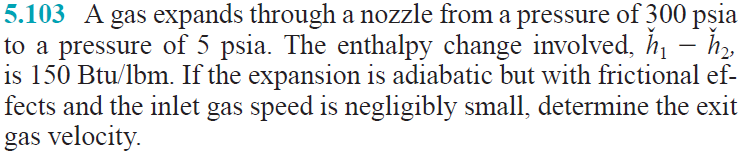

# given

u = symunit;
dh = -150*u.Btu/u.lbm;
g = 32.2*u.ft/u.s^2;

# inflow properties

p1 = (300-14.7)*u.psi;
V1 = 0;
z1 = 0;

# outflow properties

p2 = (5-14.7)*u.psi;
z2 = 0;

# conservation of energy

syms V2 positive;
V2 = solve(dh+(V2^2-V1^2)/2+g*(z2-z1) == 0);
V2 = rewrite(simplify(combine(V2)), 'US');
V2_vpa = vpa(V2, 6) %#ok

$$V2\_vpa = 2740.63\,\frac{\mathrm{ft}}{s}$$

clear V2_vpa;
clearassum;